# EE 451 Digital Signal Processing

# Homework 3

# Lisa Jacklin

# 9/15/2023

## Problem 1 : DSP: P&M 2.43

### A.compute the 10 first samples of its impulse 

--> need to include the image here for me to be able to understand what I am to solve for and display

### B. Find the input-output relation

### C. Apply the input x(n) = {1, 1, 1, ...} and compute the first 10 samples of the output. 

### D. compute the first 10 samples of the output for th einput given in part(c) by using convolution.

### E.Is the system causal? Is it stable?

## Problem 2: DSP:P&M 2.49

--> once again, I need to include the photo here in order for me to understand and display what I am doing.

### A. Determine the impulse response h(n)

### B. show that h(n) is equal to the convolution of the following signals: h1(n) = delta(n) + delta(n-1), h2(n) = (1/2)^nu(n)

n = 0:1:10; %timing range for response

h1a = impseq(0, 0, 10);

x = 1×11 logical array
   1   0   0   0   0   0   0   0   0   0   0


h1b = impseq(1, 0, 10);

x = 1×11 logical array
   0   1   0   0   0   0   0   0   0   0   0


h1 = sigadd(h1a, n, h1b, n);

n =      0     1     2     3     4     5     6     7     8     9    10



h2a = (1/2).^n;
h2b = stepseq(0, 0, 10);
h2 = sigadd(h2a, n, h2b, n);

n =      0     1     2     3     4     5     6     7     8     9    10



%now that the two signals have been established, doing the convolution of
%these two signals must be done and displayed in order to compare that part
%B is equal to part A.

prob2h = conv(h2, h1);

stem(prob2h);
title("Problem 2.b convolution of h1 and h2");
xlabel("Length of h"); ylabel("Amplitude")

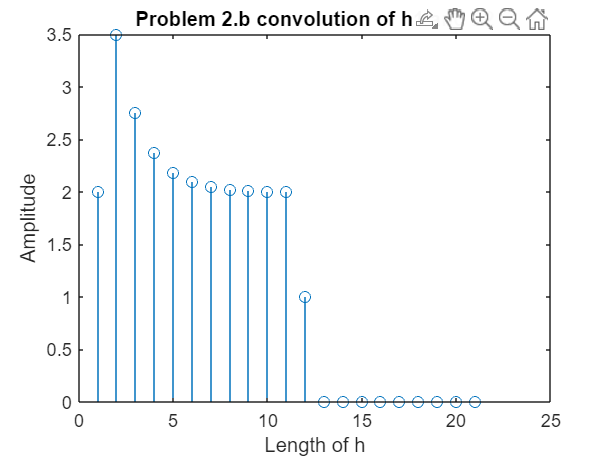

## Problem 3 DSP:P&M 3.13 Let x(n) be a sequence with z-transform X(z). Determine, in terms of X(z), the z-transforms of the following signals.

### A. x1(n) = x(n/2) if n is even, 0 if n is odd. 

### B.x2(n) = x(2n)

## Problem 4 DSP:P&M 3.16 determine the convolution of the following pairs of signals by means of the z-transform

### A. x1(n) = (1/4)^nu(n-1), x2(n) = [1 + (1/2)^n]u(n)

### B. x1(n) = u(n), x2(n) = delta(n) + (1/2)^nu(n)

### C. x1(n) = (1/2)^nu(n), x2(n) = cos(pin)u(n)

### D.x1(n) = nu(n), x2(n) = 2^nu(n-1)

## Problem 5 DSP:P&M 3.20

### A. Draw the pole-zero pattern for the signal x1(n) = r^nsin(w0n)U(n), 0 <r<1

### B. compute the z-transform X2(z), which corresponds to the pole-zero pattern in part(a).

### C.compare X1(z) with X2(z). Are they identical? If not, indicate a method to derive X1(z) from the pole-zero pattern.